# Práctica 5A. Métodos monopaso para EDOs. Euler explícito.

El objetivo de esta práctica es implementar y probar el método de Euler explícito para resolver la ecuación


$$\mathrm{(PVI)} \qquad \begin{cases}
\frac{d\mathbf{u}}{dt} (t) = \mathbf f (t, \mathbf u (t)) & t \in [t_0, T], \\
\mathbf u(t_0) = \mathbf u_0 
\end{cases}$$


## El método de Euler explícito

Recordamos la siguiente aproximación de la derivada


$$\frac{u(t+h) - u(t)}{h} = \frac{d u}{dt} (t) + O(h)$$


Así, si $u$ es solución de (PVI), tendremos que


$$\frac{u(t+h) - u(t)}{h} + O(h) = f(t, u(t))$$


Dada un paso de tiempo $h > 0$, se toman los tiempos 

$t_i = t_ 0 + h i$ con $i \in \mathbb N$. 

Se puede intentar aproximar $u(t_i)$ por unos valores $U_i$ solución de la ecuación en diferencias


$$\frac{U_{i+1} - U_i}{h} = f(t_i, U_i)$$


A este método de aproximación se lo llama *Método de Euler explícito.* El término explícito viene de que se puede construir la sucesión$U_i$ mediante


$$$ \begin{cases} U_{i+1} = U_i + h f(t_i, U_i) & i \ge 0 \\ U_0 = u_0 \end{cases}$ $$
 

donde $u_0$ es el dato inicial de la ecuación, sin resolver ninguna ecuación que involucre a $f$. Este método funciona aunque $u$ sea vectorial, y entonces hablamos de $\mathbf U_i$.

## Error de discretización

Para estudiar cuánto se aproxima se $U_i$ a $u(t_i)$, definimos el error de discretización local

$\varepsilon_i(h) = U_i - u(t_i)$.

Cuando queremos estudiarlo uniformemente en un intervalo$ [t_0,T]$, tomamos $N$ tal que $t_{N-1} < T \le t_N$ y definimos y el error de discretización global


$$\varepsilon(h) = \max_{i=1...N} \varepsilon_i (h)$$


Se dice que un método es convergente si $\varepsilon(h) \to 0$ cuando $h\to 0$.

## 1. Ecuaciones escalares

## 1.1. Implementar el método 

Escribir en el Apéndice A1 una función implemente el método de Euler explícito para la ecuación (PVI) y que responda a la sintaxis

    `[t,U]=Euler_explicito_1D(f,t_interv,u_0,N)`

donde `t_interv = [t_0, T]` es el intervalo de tiempo, y `N `es el número de pasos. Así el paso es $h=(T-t_0)/N$

## 1.2. Comprobando la convergencia

Probar el método de Euler contra la función $f(t,u) = u$ y $u(0) = 1$. La solución explícita de esta ecuación es $u(t) = e^t.$

Utilizar $T = 5, h = 2,1,0.5,0.1,0.05,0.01,0.005,0.001$

Calcular el error absoluto, y representarlo en un gráfica $(\log h, \log \varepsilon (h))$. 

Usando ajuste lineal de los valores de h próximos a 0, comprobar que $\varepsilon(h) \sim h^p$

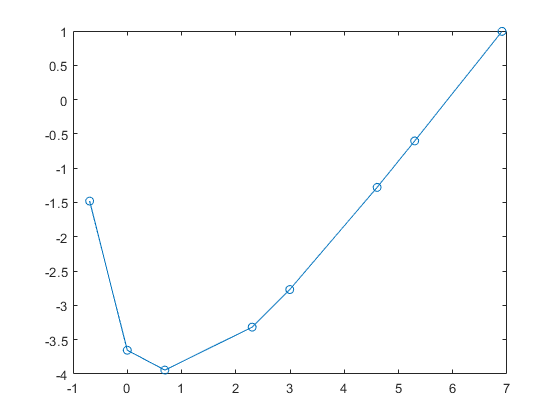

clc
clf
h = [2,1,0.5,0.1,0.05,0.01,0.005,0.001];
for i = 1:8
    clear maximo u t j t_interv
    t_interv = [0,5];
    t(1) = t_interv(1);
    u(1) = 1;
    f = @(u)[u];
    N = (t_interv(2) - t_interv(1)) / h(i);
    maximo = 0;
    for j = 1:N
        t(j+1) = t(j) + h(i);
        u(j+1) = u(j) + h(i)*f(u(j));
        if (abs(exp(t(j))-u(j)))>maximo
            error_abs = abs(exp(t(j))-u(j));
        end
    end
    error(i) = error_abs;
end

% Representacion en la gráfica
plot(-log(h),-log(error),'-o')

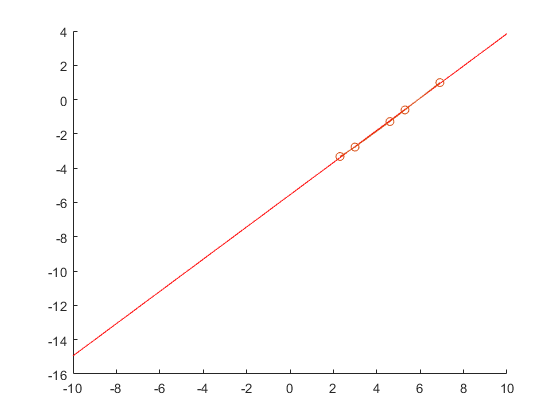


% Ajuste lineal de los valores de h próximos a 0
clear all
clc
clf
h = [0.1,0.05,0.01,0.005,0.001];
for i = 1:5
    clear maximo u t j t_interv
    t_interv = [0,5];
    t(1) = t_interv(1);
    u(1) = 1;
    f = @(u)[u];
    N = (t_interv(2) - t_interv(1)) / h(i);
    maximo = 0;
    for j = 1:N
        t(j+1) = t(j) + h(i);
        u(j+1) = u(j) + h(i)*f(u(j));
        if (abs(exp(t(j))-u(j)))>maximo
            error_abs = abs(exp(t(j))-u(j));
        end
    end
    error(i) = error_abs;
end


X=-log(h);
Y=-log(error);
%curva exponencial
A=[X',ones(5,1)];
a= inv(A'*A)*A'*Y';
%recta
val=-10:0.01:10;
Yvar=polyval(a,val);

hold on
plot(X,Y,'o')
plot(val,Yvar,'r')
plot(-log(h),-log(error),'-o')
hold off


a

a =     0.9394
   -5.5484



% La pendiente de la recta es ~1, por lo tanto p=1.


## 2. Ecuaciones vectoriales

## 2.1. Implementación

Escribir en el Apéndice A2 una función implemente el método de Euler explícito para la ecuación (PVI) y que responda a la sintaxis

    `[t,U]=Euler_explicito(f,t_interv,u_0,N)`

## 2.2. Diagramas de fase: oscilador armónico simple

Estudiar la ecuación


$$\begin{cases}
m L \theta '' (t) + 2 L \beta \theta' (t) + mg (\theta(t)) = F & t \in [0,T] \\
\theta(0) = \theta_0, \\
\theta' (0) = w_0.
\end{cases}$$


Se consideran los valores $m = 1 [kg] , g = 9.8 [m/s^2], T = 10.$ Estudiar, para $F= 0, L = 1 [m]$, los diferentes comportamientos del sistema con $\beta = 0, 0.25, 1.5$ partiendo del dato inicial $\theta_0 = 0, w_0 = 0.5$. Representar tanto $(t, \theta(t))$ como el diagrama de fase $(\theta, \dot \theta)$.

Utilizar paso de tiempo $h = 0.01, 0.0001$¿es fidedigno el resultado con respecto a las soluciones explícitas conocidas? 

A =          0    1.0000
   -9.8000         0


A =          0    1.0000
   -9.8000   -0.5000


A =          0    1.0000
   -9.8000   -3.0000


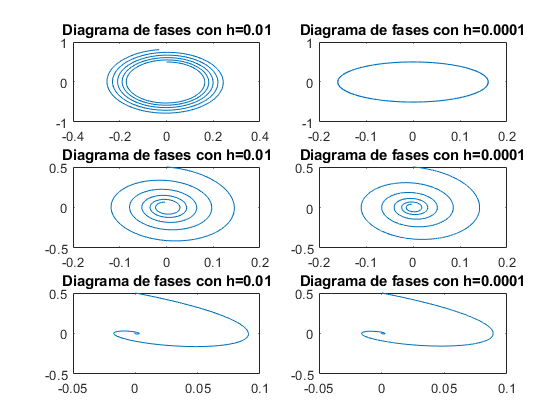

B=[0,0.25,1.5];
h=[0.01,0.0001];
m=1;
g=9.8;
L=1;
t_interv=[0,10];
u_0=[0,0.5];
z=0;
for i=1:3
    clear t U N A F 
    A=[0,1;-9.8,-2*B(i)]
    F=@(t,U)[A*U];
    U(1,1)=u_0(1);
    U(2,1)=u_0(2);
    t(1)=0;
    for j=1:length(h)
        N=(t_interv(2)-t_interv(1))/h(j);
        for k=1:N
            t(k+1)=t(k)+h(j);
            U(:,k+1)=U(:,k)+h(j)*F(t(k),U(:,k));
        end
        z=z+1;
        subplot(3,2,z);
        plot(t,U(1,:));
        title(['Gráfica de solución con h=',num2str(h(j)),])
        subplot(3,2,z)
        plot(U(1,:),U(2,:))
        title(['Diagrama de fases con h=',num2str(h(j)),])
    end
    
end

## Apéndice A. Implementación del método de Euler explícito

## A1. Versión escalar

function [t,U]=Euler_explicito_1D(f,t_interv,u_0,N)
    t(1) = t_interv(1);
    U(1) = u_0;
    h = (t_interv(2)-t_interv(1))/N;
    for i = 1:N
        t(i+1) = t(i) + h;
        U(i+1) = U(i) + h*f(t(i),U(i));       
    end 
end
        
    

## A2. Versión vectorial

function [t,U]=Euler_explicito(f,t_interv,u_0,N)
    U(1,1)=u_0(1);
    U(2,1)=u_0(2);
    for i=1:length(N)
        h = (t_interv(2)-t_interv(1))/N;
        for k=1:N
            t(k+1)=t(k)+h;
            U(:,k+1)=U(:,k)+h*f(t(k),U(:,k));
        end
    end
end  
